1- plot:

Y = HW1_sig(810198356);
t = 0:0.00001:20;
plot(t,Y)
xlabel('time')
ylabel('signal')
title('part 1')

2- lowpass filter:

f = 900
RC = 1/(f)
sys_LPF = tf(1,[RC 1])
u = Y;
[y_filtered, t_filtered] = lsim(sys_LPF,u,t);

lsim(sys_LPF,u,t)
xlabel('time')
ylabel('signal')
title('low pass filter')

3- checking different RC values:

for i=1:5
    f_temp = f+i;
    RC_temp = 1/(f_temp);
    sys_LPF = tf(1,[RC_temp 1]);
    [y2,t2] = lsim(sys_LPF,y_filtered, t_filtered);
    plot(t2,y2)
    legend()
    hold on
end
xlabel('time')
ylabel('signal')
title('different RC values')
hold off

4- bandpass filter:

fh = 100.5

fh = 100.5000

fl = 99.5

fl = 99.5000

RhCh = 1/(fl)

RhCh = 0.0100

RlCl = 1/(fh)

RlCl = 0.0101

sys_BPF = tf([RhCh ,0],[RhCh*RlCl ,RhCh+RlCl ,1])

sys_BPF =
 
         0.00995 s
  -----------------------
  0.0001 s^2 + 0.02 s + 1
 
Continuous-time transfer function.



[y_BPF,t_BPF]=lsim(sys_BPF,y_filtered, t_filtered)

y_BPF =          0
    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0005
    0.0008
    0.0012


t_BPF =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


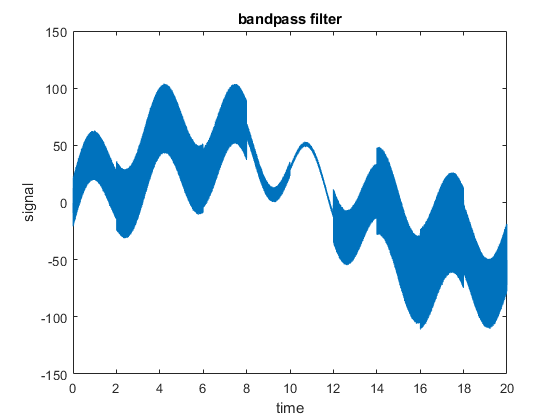

xlabel('time')
ylabel('signal')
title('bandpass filter')

5- bode diagram:

magnitude_change = bodeoptions;
magnitude_change.MagUnits = "abs";
bodemag(sys_BPF,magnitude_change)

multiplying the coefficient:

k = 10
bodemag(k*sys_BPF,magnitude_change)
lsim(k*sys_BPF,y_filtered, t_filtered)
title('signal with k=10 coefficient')

6- exponential filter:

G = sys_BPF;
F = k*G;
hold off
for n=1:10
    bodemag((F^n),magnitude_change)
    legend()
    hold on
end
hold off

exponential function lsim:

G = sys_BPF;
F = k*G;
hold off
for n=1:10
    lsim(F^n,y_filtered, t_filtered)
    hold on
end
hold off

for 300 Hz:

fh2 = 300.5

fl2 = 300.5000

fl2 = 299.5

fh2 = 299.5000

RhCh2 = 1/(fl2)

RhCh2 = 0.0033

RlCl2 = 1/(fh2)

RlCl2 = 0.0033

sys_BPF2 = tf([RhCh2 ,0],[RhCh2*RlCl2 ,RhCh2+RlCl2 ,1])

sys_BPF2 =
 
            0.003339 s
  ------------------------------
  1.111e-05 s^2 + 0.006667 s + 1
 
Continuous-time transfer function.



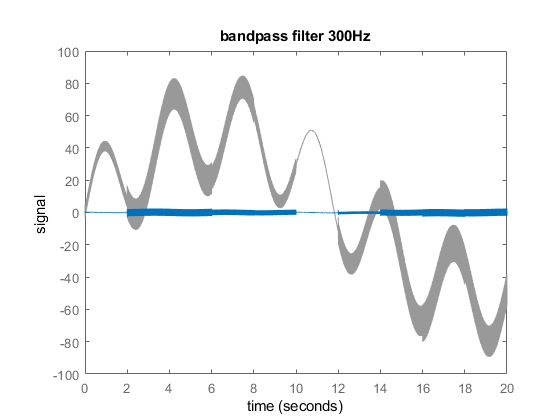

lsim(sys_BPF2,y_filtered, t_filtered)
xlabel('time')
ylabel('signal')
title('bandpass filter 300Hz')

bodemag(sys_BPF2,magnitude_change)

k2 = 20
bodemag(k2*sys_BPF2,magnitude_change)
lsim(k2*sys_BPF2,y_filtered, t_filtered)
title('signal with k=20 coefficient')

G2 = sys_BPF2;
F2 = k2*G2;
hold off
for n=1:10
    bodemag((F2^n),magnitude_change)
    legend()
    hold on
end
hold off

for n=1:10
    lsim(F2^numel,y_filtered, t_filtered)
    hold on
end
hold off

for 600 Hz:

fh3 = 600.5
fl3 = 599.5
RhCh3 = 1/(fl3)
RlCl3 = 1/(fh3)
sys_BPF3 = tf([RhCh3 ,0],[RhCh3*RlCl3 ,RhCh3+RlCl3 ,1])
lsim(sys_BPF3,y_filtered, t_filtered)
xlabel('time')
ylabel('signal')
title('bandpass filter 600Hz')

bodemag(sys_BPF3,magnitude_change)

k3 = 30
bodemag(k3*sys_BPF3,magnitude_change)
lsim(k3*sys_BPF3,y_filtered, t_filtered)
title('signal with k=30 coefficient')

G3 = sys_BPF3;
F3 = 30*G3;
hold off
for n=1:10
    bodemag((F3^n),magnitude_change)
    legend()
    hold on
end
hold off

for n=1:10
    lsim(F3^n,y_filtered, t_filtered)
    hold on
end
hold off

for 900 Hz:

fh4 = 900.5
fl4 = 899.5
RhCh4 = 1/(fl4)
RlCl4 = 1/(fh4)
sys_BPF4 = tf([RhCh4 ,0],[RhCh4*RlCl4 ,RhCh4+RlCl4 ,1])
lsim(sys_BPF4,y_filtered, t_filtered)
xlabel('time')
ylabel('signal')
title('bandpass filter 900Hz')

bodemag(sys_BPF4,magnitude_change)

k4 = 40
bodemag(k4*sys_BPF4,magnitude_change)

lsim(40*sys_BPF4,y_filtered, t_filtered)
title('signal with k=40 coefficient')

G4 = sys_BPF4;
F4 = k4*G4;
hold off
for n=1:10
    bodemag((F4^n),magnitude_change)
    legend()
    hold on
end
hold off

for n=1:10
    lsim(F4^n,y_filtered, t_filtered)
    hold on
end
hold off

10- highpass filter:

f = 900
RC = 1/(f)
sys_HPF = tf(RC,[RC 1])
lsim(sys_LPF,u,t)
xlabel('time')
ylabel('signal')
title('high pass filter')

f = 900 

f = 900

RC = 1/(f)

RC = 0.0011

sys_HPF = tf(RC,[RC 1])

sys_HPF =
 
     0.001111
  --------------
  0.001111 s + 1
 
Continuous-time transfer function.



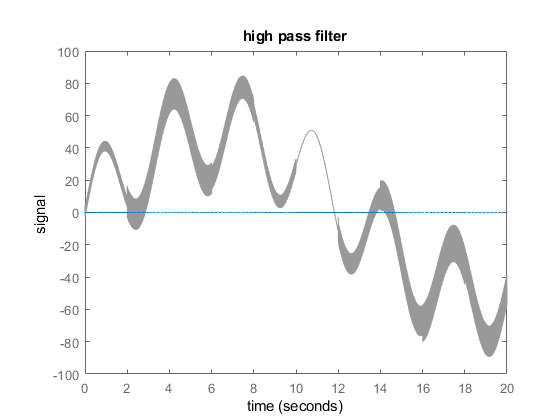

lsim(sys_HPF,y_filtered,t)
xlabel('time')
ylabel('signal')
title('high pass filter')

f = 900 
RC = 1/(f)
sys_HPF = tf(RC,[RC 1])
lsim(sys_HPF,y_BPF,t)
xlabel('time')
ylabel('signal')
title('high pass filter')

11- Notch filter:

fr = 600

fr = 599.5000

LC = 1/(fr^2)

LC = 2.7824e-06

CR = 1/(fr^2)

CR = 2.7824e-06

sys_notch = tf([LC 0 1],[LC CR 1])

sys_notch =
 
         2.782e-06 s^2 + 1
  -------------------------------
  2.782e-06 s^2 + 2.782e-06 s + 1
 
Continuous-time transfer function.



[y_notch, t_notch] = lsim(sys_notch,y_filtered,t)

y_notch =    -0.0000
    0.0027
    0.0172
    0.0422
    0.0775
    0.1193
    0.1681
    0.2308
    0.3086
    0.3952


t_notch =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


y_600 = y_filtered - y_notch

y_600 =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


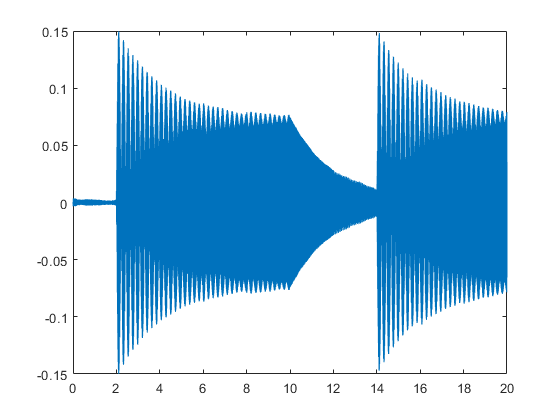

plot(t,y_600)